clc;
clear;
close all;

%% PARAMETERS
num_nodes = 5;            % Number of nodes
sim_time = 5;             % seconds
dt = 0.001;
time = 0:dt:sim_time;

lambda = 20;              % packet generation rate (per node)
packet_size = 1000;       % bits
data_rate = 1e6;          % 1 Mbps

token_hold_time = 0.01;   % time a node holds token

%% INITIALIZATION
queues = zeros(1, num_nodes);   % packets waiting at each node
current_node = 1;               % token starts at node 1

total_packets = 0;
sent_packets = 0;
delay = [];

%% SIMULATION LOOP
for t_idx = 1:length(time)
    
    % Packet generation (simple random without toolbox)
    for i = 1:num_nodes
        if rand < lambda*dt
            queues(i) = queues(i) + 1;
            total_packets = total_packets + 1;
        end
    end
    
    % Token passing logic
    if queues(current_node) > 0
        
        % Transmit one packet
        tx_time = packet_size / data_rate;
        
        queues(current_node) = queues(current_node) - 1;
        sent_packets = sent_packets + 1;
        
        delay = [delay tx_time];
    end
    
    % Move token after hold time
    if mod(t_idx, round(token_hold_time/dt)) == 0
        current_node = current_node + 1;
        if current_node > num_nodes
            current_node = 1;
        end
    end
end

%% PERFORMANCE METRICS

throughput = (sent_packets * packet_size) / sim_time;
utilization = sent_packets / total_packets * 100;

if ~isempty(delay)
    avg_delay = mean(delay) * 1000;
else
    avg_delay = 0;
end

%% RESULTS

fprintf('Total Packets Generated = %d\n', total_packets);

Total Packets Generated = 518


fprintf('Packets Sent = %d\n', sent_packets);

Packets Sent = 516


fprintf('Throughput = %.2f bps\n', throughput);

Throughput = 103200.00 bps


fprintf('Utilization = %.2f %%\n', utilization);

Utilization = 99.61 %


fprintf('Average Delay = %.4f ms\n', avg_delay);

Average Delay = 1.0000 ms


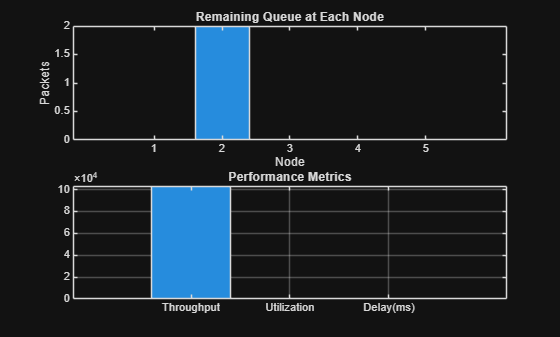


%% PLOTS

figure;

subplot(2,1,1);
bar(queues);
title('Remaining Queue at Each Node');
xlabel('Node');
ylabel('Packets');

subplot(2,1,2);
bar([throughput, utilization, avg_delay]);
set(gca, 'XTickLabel', {'Throughput','Utilization','Delay(ms)'});
title('Performance Metrics');
grid on;